clear 

% Construct the primal spatial grid
domain_x = [0,1];
Nx  = 101;

grid_primal = Grid1DUnifPrimal(domain_x,Nx);
gsp_primal   = GridSpace1D(grid_primal);

% Define a constant acoustic medium
medium = AcousticMedium1D.constant( ...
    BetaValue=2, ...
    KappaValue=3);

% Sample the medium onto the grids
[K,B,~,cMax] = sampleMedium1D(gsp_primal,medium)

K =   GridFunction with properties:

      grid: [1×1 GridSpace1D]
    values: [101×1 double]
     label: "Bulk modulus"
     units: "Pa"
         N: 101
       dim: 1


B =   GridFunction with properties:

      grid: [1×1 GridSpace1D]
    values: [100×1 double]
     label: "Buoyancy"
     units: "m^3/kg"
         N: 100
       dim: 1


cMax = 2.4495

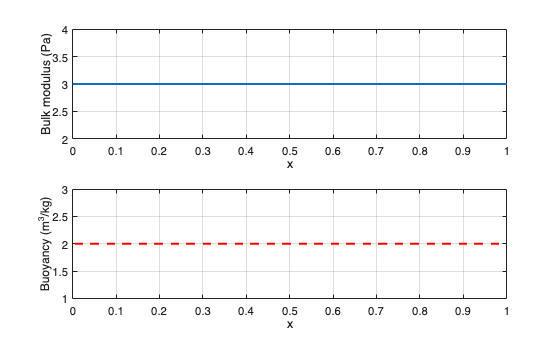


% Plotting medium parameters
figure

subplot(2,1,1)
K.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B.plot("--r","LineWidth",1.5,"MarkerSize",3);
grid on

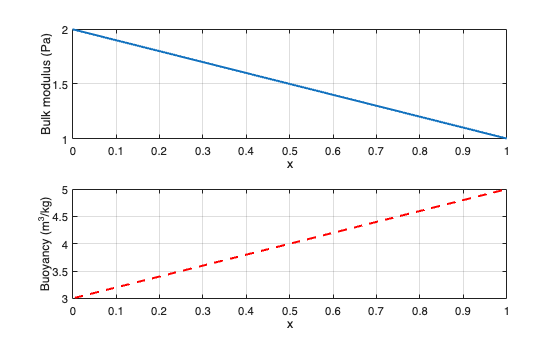

% Define a linear acoustic medium
medium = AcousticMedium1D.linear( ...
    KappaRange = [2,1], ...
    BetaRange  = [3,5], ...
    Domain     = domain_x);

% Sample the medium onto the grids
[K,B] = sampleMedium1D(gsp_primal,medium);

% Plotting medium parameters
figure

subplot(2,1,1)
K.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B.plot("--r","LineWidth",1.5,"MarkerSize",3);
grid on

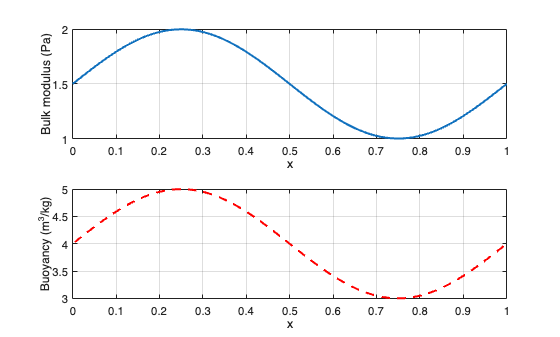

% Define a smooth acoustic medium
medium = AcousticMedium1D.smooth( ...
    KappaRange = [1,2], ...
    BetaRange  = [3,5], ...
    Domain     = domain_x);

% Sample the medium onto the grids
[K,B] = sampleMedium1D(gsp_primal,medium);

% Plotting medium parameters
figure

subplot(2,1,1)
K.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B.plot("--r","LineWidth",1.5,"MarkerSize",3);
grid on

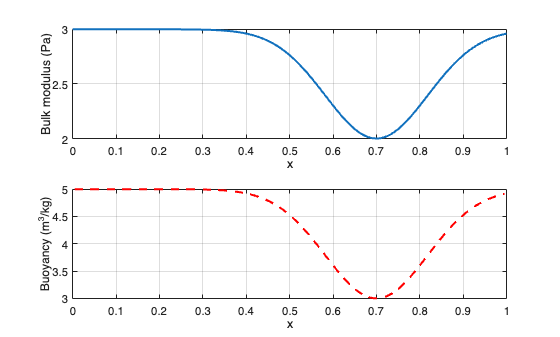

% Define a Gaussian dip acoustic medium
L = diff(domain_x);
xc = domain_x(1) + L*0.7;
medium = AcousticMedium1D.gaussian( ...
    KappaInside  = 2, ...
    KappaOutside = 3, ...
    BetaInside   = 3, ...
    BetaOutside  = 5, ...
    Center     = xc, ...
    Width      = L/6 );

% Sample the medium onto the grids
[K,B] = sampleMedium1D(gsp_primal,medium);

% Plotting medium parameters
figure

subplot(2,1,1)
K.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B.plot("--r","LineWidth",1.5,"MarkerSize",3);
grid on

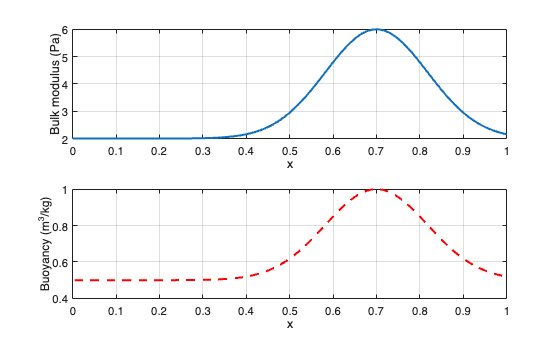

% Define a Gaussian peak acoustic medium
L = diff(domain_x);
xc = domain_x(1) + L*0.7;
medium = AcousticMedium1D.gaussian( ...
    KappaInside  = 6, ...
    KappaOutside = 2, ...
    BetaInside   = 1, ...
    BetaOutside  = 0.5, ...
    Center     = xc, ...
    Width      = L/6 );

% Sample the medium onto the grids
[K,B] = sampleMedium1D(gsp_primal,medium);

% Plotting medium parameters
figure

subplot(2,1,1)
K.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B.plot("--r","LineWidth",1.5,"MarkerSize",3);
grid on